# **Trabalho 1 de AM2 - Interface Livescript**


clear;
cla;
clc;

%  ______   _   _   _____ 
%  | ___ \ | | | | |_   _|
%  | |_/ / | | | |   | |  
%  |  __/  | | | |   | |  
%  | |     \ \_/ /  _| |_ 
%  \_|      \___/  |_____| 

% Resolução de Problemas de Valor Inicial
% com recurso a Métodos Numéricos

escolha = "Todos";

syms y(t);

s  =  "-2*t*y";
a  =  0;
b  =  1.5;
n  =  3;
y0 =  2;
f = @(t,y) eval(vectorize(s));

try
    MEuler(f,a,b,n,y0);
catch ME
    addpath Métodos
end

## **Verificação do Input**


try
    f(t,y);
catch
    errordlg("Introduza uma função em t e y","Erro");
    return
end

$$ans(t) = -2\,t\,y\left(t\right)$$

if (not(isscalar(a) && isreal(a)))
    errordlg("O número introduzido para a é inválido","Erro");
    return
end

if (not(isscalar(b) && isreal(b) && b>a))
    errordlg("O número introduzido para b é inválido","Erro");
    return
end

if (not(isscalar(n) && isreal(n)))
    errordlg("O número introduzido para n é inválido","Erro");
    return
end

if (not(isscalar(y0) && isreal(y0))) 
    errordlg("O número introduzido para y0 é inválido","Erro");
    return
end


## **Cálculo da solução exata**

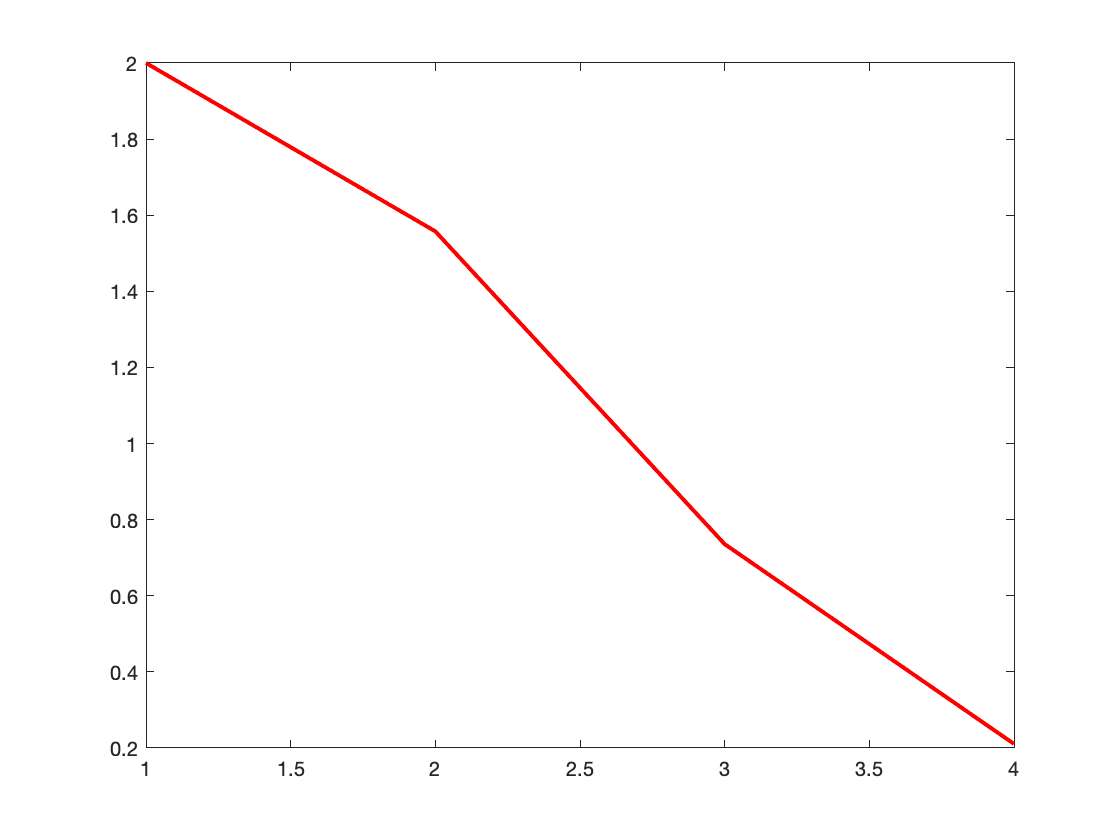


xExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
g = @(t) eval(vectorize(char(xExata)));
h = (b-a)/n;
t = a:h:b;
yExata = g(t);
plot(yExata,'-r','LineWidth',2);
hold("on");

## **Cálculo da solução a partir do método selecionado**


switch escolha
    case "Euler"
        sol = MEuler(f,a,b,n,y0);
        plot(sol,'k--','LineWidth',2);
        legend('Exata','Euler');
        hold("on");
        erro = abs(yExata - sol);
    case "Euler+"
        sol = MEulerMelhorado(f,a,b,n,y0);
        plot(sol,'k--','LineWidth',2);
        legend('Exata','Euler+');
        hold("on");
        erro = abs(yExata - sol);
    case "RK2"
        sol = NRK2(f,a,b,n,y0);
        plot(sol,'k--','LineWidth',2);
        legend('Exata','RK2');
        hold("on");
        erro = abs(yExata - sol);
    case "RK4"
        sol = NRK4(f,a,b,n,y0);
        plot(sol,'k--','LineWidth',2);
        legend('Exata','RK4');
        hold("on");
        erro = abs(yExata - sol);
    case "ODE45"
        sol = NODE45(f,a,b,n,y0);
        plot(sol,'k--','LineWidth',2);
        legend('Exata','ODE45');
        hold("on");
        erro = abs(yExata - sol);
    case "PM"
        sol = NPM(f,a,b,n,y0);
        plot(sol,'k--','LineWidth',2);
        legend('Exata','PM');
        hold("on");
        erro = abs(yExata - sol);
    case "Todos"
        Euler = MEuler(f,a,b,n,y0);
        EulerM = MEulerMelhorado(f,a,b,n,y0);
        RK2 = NRK2(f,a,b,n,y0);
        RK4 = NRK4(f,a,b,n,y0);
        ODE45 = NODE45(f,a,b,n,y0);
        PM = NPM(f,a,b,n,y0);
        
        erroEuler = yExata(end) - Euler(end);
        erroEulerM = yExata(end) - EulerM(end);
        erroRK2 = yExata(end) - RK2(end);
        erroRK4 = yExata(end) - RK4(end);
        erroODE45 = yExata(end) - ODE45(end);
        erroPM = yExata(end) - PM(end);
end

'MEuler' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/asuryu/Documents/GitHub/AM2-Trabalho01/Métodos

Change the MATLAB current folder or add its folder to the MATLAB path.


title('Gráfico das soluções da PVI');


## **Tabela**


switch escolha
    case "Euler"
        tabela = [t.',yExata.',sol.', erro.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler','Erro'})
    case "Euler+"
        tabela = [t.',yExata.',sol.', erro.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler+','Erro'})
    case "RK2"
        tabela = [t.',yExata.',sol.', erro.'];
        array2table(tabela,"VariableNames",{'t','Exata','RK2','Erro'})
    case "RK4"
        tabela = [t.',yExata.',sol.', erro.'];
        array2table(tabela,"VariableNames",{'t','Exata','RK4','Erro'})
    case "ODE45"
        tabela = [t.',yExata.',sol.', erro.'];
        array2table(tabela,"VariableNames",{'t','Exata','ODE45','Erro'})
    case "PM"
        tabela = [t.',yExata.',sol.', erro.'];
        array2table(tabela,"VariableNames",{'t','Exata','PM','Erro'})
    case "Todos"
        tabela = [t.',yExata.',Euler.',EulerM.',RK2.',RK4.',ODE45.',PM.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler','Euler+','RK2','RK4','ODE45','PM'})
end

## **Plot dos gráficos**


if(escolha == "Todos")
    plot(Euler, '--','LineWidth',2);
    plot(EulerM, '-','LineWidth',2);
    plot(RK2, '--','LineWidth',2);
    plot(RK4, '--','LineWidth',2);
    plot(ODE45, '--','LineWidth',2);
    plot(PM, '--','LineWidth',2);
    legend('Exata','Euler','Euler+','RK2','RK4','ODE45', 'PM');
    hold("on");
else
    plot(sol);
    legend('Exata',escolha);
    hold("on");
end

## **Soluções Finais**

disp("SOLUÇÃO EXATA:    " + yExata(end));
if(escolha == "Todos")
    disp("Solução Euler:    " + Euler(end));
    disp("Solução Euler+:   " + EulerM(end));
    disp("Solução RK2:      " + RK2(end));
    disp("Solução RK4:      " + RK4(end));
    disp("Solução ODE45:    " + ODE45(end));
    disp("Solução PM:       " + PM(end));

    fprintf('\n ')
    
    disp("Iterações Euler:    " + length(Euler));
    disp("Iterações Euler+:   " + length(EulerM));
    disp("Iterações RK2:      " + length(RK2));
    disp("Iterações RK4:      " + length(RK4));
    disp("Iterações ODE45:    " + length(ODE45));
    disp("Iterações PM:       " + length(PM));
else
    disp("Solução " + escolha + ":    " + sol(end));
    fprintf('\n ')
    disp("Iterações " + escolha + ":    " + length(sol));
end